# Radiation Therapy 

### Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

if strcmp(getenv('USERNAME'), 'aryan')
    cd C:\Users\aryan\Documents\documents_general\dablab_files\dablab_repo\optimizationOnRamp\radiationTherapy\
end

addpath functions\ %remove in matlab online

prob = optimproblem("Description","Radiation Therapy Optimization");
I = optimvar("I",8,"LowerBound",0);

gridHorz = repmat(4:-1:1, 4, 1);
gridVert = transpose(gridHorz);
tumorIdx = [2, 2; 3, 1; 3, 2; 4, 3];
spinalIdx = [3, 3];

minIntensityForTumor = 7;

[d, tumorSum, spinalSum] = computeTotalCellResponse(gridHorz, tumorIdx, spinalIdx);
D = transpose(d) * I;
spinalResponse = transpose(spinalSum) * I;
prob.Objective = D;
prob.Constraints.spinal = spinalResponse <= 5;
tumorResponseBeamWise = tumorSum .* I;
intensityCoefficients = intensityOnTumor(gridHorz, tumorIdx);
intensities = transpose(intensityCoefficients) * I

intensities =   4×1 Linear OptimizationExpression array with properties:

    IndexNames: {{}  {}}
     Variables: [1×1 struct] containing 1 OptimizationVariable

  See expression formulation with show.


% Use a cell array to dynamically create variables based on the size of intensities
numTumors = size(tumorIdx, 1);

### Dangerous code: Using `assignin `is a bad habit.

`assignin `can dynamically create new variables, given a list of variable names and variable values.

varNames = {'A', 'B', 'C', 'D'}';
vars = cell(length(varNames), 1);

% Assign the variables using dynamic variable names
N = size(gridHorz, 1);

for i = 1:numTumors
    vars{i} = intensities(i);
    assignin('caller', varNames{i}, vars{i});
end

prob.Constraints.A = A >= minIntensityForTumor;
prob.Constraints.B = C >= minIntensityForTumor; %matlab has specified B and C to be so
prob.Constraints.C = B >= minIntensityForTumor;
prob.Constraints.D = D >= minIntensityForTumor;

[sol, optval] = solve(prob)

Solving problem using linprog.

Optimal solution found.



sol = struct with fields:
    I: [8×1 double]


optval = 44.9167

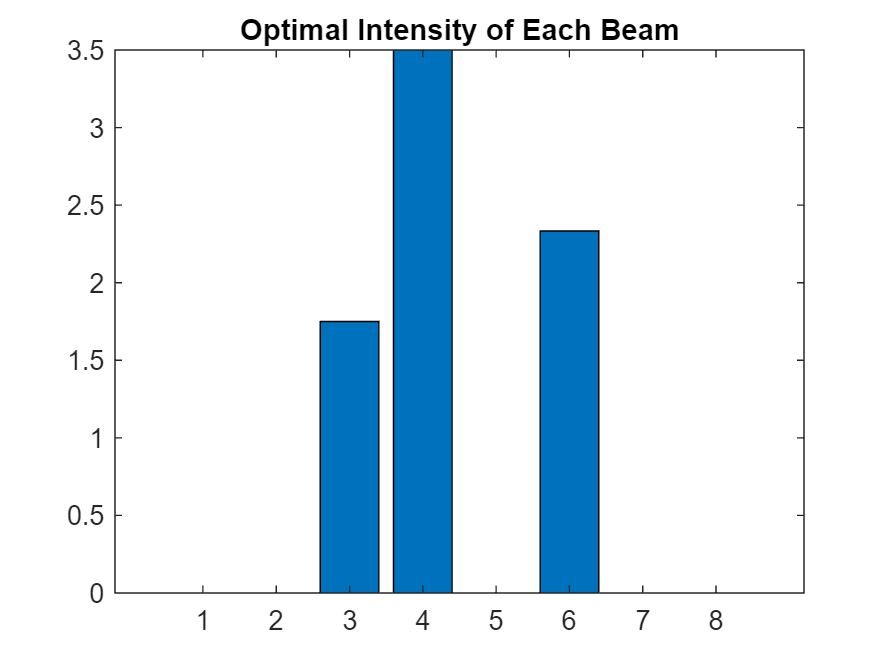

bar(sol.I);
title("Optimal Intensity of Each Beam");

check = evaluate(spinalResponse, sol);

function [totalCellResponse, tumorSum, spinalSum] = computeTotalCellResponse(gridHorz, tumorIdx, spinalIdx)
    N = size(gridHorz, 1);
    totalCellResponse = zeros(2*N, 1);
    gridVert = transpose(gridHorz);
    
    tumorSum = totalTumorResponse(gridHorz, tumorIdx);
    spinalSum = totalTumorResponse(gridHorz, spinalIdx);

    for row = 1:N
        for col = 1:N
            totalCellResponse(row) = totalCellResponse(row) + gridHorz(row, col);
            totalCellResponse(N+col) = totalCellResponse(N+col) + gridVert(row, col);
        end
    end
    % totalCellResponse = totalCellResponse - tumorSum - spinalSum;
    totalCellResponse = totalCellResponse - tumorSum;

end

function tumorSum = totalTumorResponse(gridHorz, tumorIdx)
    N = size(gridHorz, 1);
    tumorSum = zeros(2*N, 1);
    gridVert = transpose(gridHorz);
    
    for currentTumorIndex = transpose(tumorIdx)
        row = currentTumorIndex(1);
        col = currentTumorIndex(2);
        tumorSum(row) = tumorSum(row) + gridHorz(row, col);
        tumorSum(N+col) = tumorSum(N+col) + gridVert(row, col);
    end

end

function intensities = intensityOnTumor(gridHorz, tumorIdx)
    N = size(gridHorz, 1);
    numTumors = size(tumorIdx, 1);
    intensities = zeros(2*N, numTumors);
    gridVert = transpose(gridHorz);
    for tumorNum = 1:numTumors
        row = tumorIdx(tumorNum, 1);
        col = tumorIdx(tumorNum, 2);
        intensities(row, tumorNum) = gridHorz(row, col);
        intensities(N+col, tumorNum) = gridVert(row, col);
    end
end
